arduino = serialport("COM6", 500000);
configureTerminator(arduino, "LF"); % Configure terminator as line feed

data = []


data =

     []



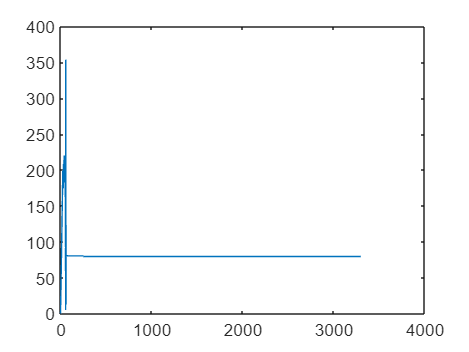

Error reading data from the serial port.
Transport object has become invalid.

num1 = zeros(1000000, 1);
Num2 = zeros(1000000, 1);

figure

tic; % Start timer
while 1

    % Read a line of data from the serial port
    line = readline(arduino);

    % Split the line into substrings using comma as the delimiter
   data = split(line, ',');
   
   dat1 = str2double(data{1});
   dat2 = str2double(data{2});

num1 = [num1; dat1]; 
   Num2 = [Num2; dat2];
    
Num1 = num1 .* 10.^-3;
NUM1 = Num1(100001:length(Num1));
NUM2 = Num2(100001:length(Num2));

plot(NUM1,NUM2)

end

Num1

Num1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Num2

Num2 = 1.0e+04 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



NUM1 = Num1(1000001:length(Num1))

NUM1 =     3.2890
    3.4900
    3.6920
    3.8930
    4.0940
    4.2950
    4.4960
    4.6970
    4.8990
    5.1000


NUM2 = Num2(1000001:length(Num2))

NUM2 = 1.0e+04 *

    9.9341
    9.9345
    9.9345
    9.9345
    9.9345
    9.9346
    9.9346
    9.9346
    9.9346
    9.9346


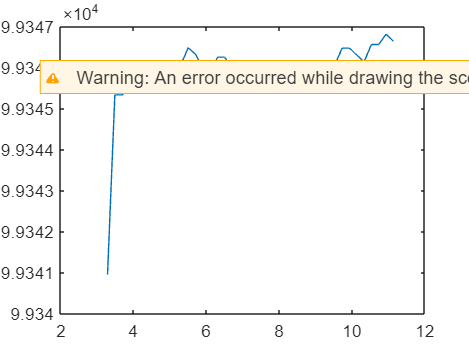


plot(NUM1,NUM2)